# **ASSIGNMENT 1**

1. Create a matrix 3x4 matrix named x that looks like this:

100    1234   1245     1252

1        2          3           4

1        3          5           6

x = [100 1234 1245 1252; 1 2 3 4; 1 3 5 6]

x =          100        1234        1245        1252
           1           2           3           4
           1           3           5           6


2. Run the below code to create the matrix called x.

    Create a 2x2  **table** called x`table` (all lowercase) that stores only values in the first two rows and first two columns of `X1.`

- Use column names of 'dollar' for column 1 and 'yuan' for column 2.

- Use row names of 'gold' and 'silver'

    Row and column names are case sensitive, so use all lowercase letters for both

x = [ 1 6 3 1; 7 3 6 0; 1 9 4 1]

x =      1     6     3     1
     7     3     6     0
     1     9     4     1


x1 = x(1:2, 1:2)

x1 =      1     6
     7     3


xtable = array2table(x1)

xtable = 2×2 table
    x11    x12
    ___    ___

     1      6 
     7      3 


xtable.Properties.VariableNames = {'dollar','yuan'}

xtable = 2×2 table
    dollar    yuan
    ______    ____

      1        6  
      7        3  


xtable.Properties.RowNames = {'gold','silver'}

xtable = 2×2 table
              dollar    yuan
              ______    ____

    gold        1        6  
    silver      7        3  


xtable

xtable = 2×2 table
              dollar    yuan
              ______    ____

    gold        1        6  
    silver      7        3  


3. First, create a matrix called `B` with the following form:

   1      2     3     4      5

   6     7      8     9     10

   11  12    13   14    15

   Next, define the following three variables:

-    A 3x1 column vector called `B1` that stores only the second column of `B.`

-    A 1x5 row vector called `B2` that stores only the third row of `B`.

-    A 2x3 matrix called `B3` that stores the intersection of columns 2, 3, 4 with rows 1 and 3 (i.e. the values 2, 3, 4, 12, 13 ,14).

 B = [1 2 3 4 5; 6 7 8 9 10;11 12 13 14 15]

B =      1     2     3     4     5
     6     7     8     9    10
    11    12    13    14    15


 B1 = B(:,2)

B1 =      2
     7
    12


 B2 = B(3,:)

B2 =     11    12    13    14    15


 B3 = B([1,3],[2,3,4])

B3 =      2     3     4
    12    13    14


4. Run the `readtable` statement below to view a set of monthly portfolio returns stored in the data table called` portfolio_returns`.

The arithmetic average return of the set is the simple mean 

The geometric average return of the set  is calculated as , which represents the average growth rate.

Use Matlab to calculate the arithmetic and geometric mean monthly returns.  **You cannot use the functions mean or geomean to answer this question.**

Assign the arithmetic average to a variable named `meanA.`

Assign the geometric average to a variable named `meanG`.

portfolio_returns = readtable('means_calc.xlsx')

portfolio_returns = 12×2 table
     Month     Portfolio_Rets
    _______    ______________

    {'Jan'}        0.19578   
    {'Feb'}         0.3109   
    {'Mar'}       0.049453   
    {'Apr'}        0.22408   
    {'May'}        0.25244   
    {'Jun'}        0.18939   
    {'Jul'}       -0.16911   
    {'Aug'}       0.047867   
    {'Sep'}       -0.28025   
    {'Oct'}       0.038398   
    {'Nov'}      -0.042972   
    {'Dec'}       0.095792   


returns = portfolio_returns.Portfolio_Rets

returns =     0.1958
    0.3109
    0.0495
    0.2241
    0.2524
    0.1894
   -0.1691
    0.0479
   -0.2802
    0.0384


n = length(returns)

n = 12

meanA = sum(returns)/n

meanA = 0.0760

product_returns = prod(1 + returns)

product_returns = 2.0470

meanG = product_returns^(1/n) - 1

meanG = 0.0615

5. Run the `readtable` command below to see monthly returns on an active portfolio and its benchmark.

    Let  and  be the portfolio and benchmark returns at time *t*, respectively.  The average active return on the portfolio over the                                                                 interval  is calculated as   where   denotes the geometric mean. Note that this difference between geometric means is not the same as the geometric mean of the differences:

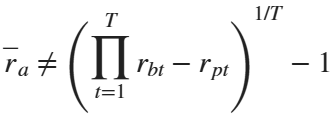

Use Matlab to calculate the average active return as the geometric mean return on the portfolio less the geometric mean return on the benchmark.  **Your solution cannot use the geomean function.**

- Assign the value of the geometric mean portfolio return to `mean_Rp`.

- Assign the value of the geometric mean benchmark return to `mean_Rb.`

- Assign the value of the geometric mean active return to `mean_Ra`.

ret_table = readtable('RpRb_1.xlsx')

ret_table = 12×3 table
     Month     Portfolio_Rets    Benchmark_Rets
    _______    ______________    ______________

    {'Jan'}        0.19578           0.19447   
    {'Feb'}         0.3109           0.27917   
    {'Mar'}       0.049453          0.071002   
    {'Apr'}        0.22408           0.23799   
    {'May'}        0.25244           0.28539   
    {'Jun'}        0.18939           0.19529   
    {'Jul'}       -0.16911          -0.15501   
    {'Aug'}       0.047867          0.024838   
    {'Sep'}       -0.28025          -0.24306   
    {'Oct'}       0.038398          0.085827   
    {'Nov'}      -0.042972         -0.050598   
    {'Dec'}       0.095792          0.081896   


Rp = ret_table.Portfolio_Rets

Rp =     0.1958
    0.3109
    0.0495
    0.2241
    0.2524
    0.1894
   -0.1691
    0.0479
   -0.2802
    0.0384


Rb = ret_table.Benchmark_Rets

Rb =     0.1945
    0.2792
    0.0710
    0.2380
    0.2854
    0.1953
   -0.1550
    0.0248
   -0.2431
    0.0858


mean_Rp = prod(1+ Rp)^(1/length(Rp))-1

mean_Rp = 0.0615

annualized_Rp = (1+mean_Rp)^(12)-1

annualized_Rp = 1.0470

mean_Rb = prod(1+ Rb)^(1/length(Rb))-1

mean_Rb = 0.0709

annualized_Rb = (1+mean_Rb)^(12)-1

annualized_Rb = 1.2755

mean_Ra = mean_Rp - mean_Rb

mean_Ra = -0.0094

6. The tracking error of a portfolio return is the standard deviation of the active return.  If  and  are the portfolio return at time *t*, respectively, then  is the active return at time *t*, and the tracking error of the portfolio is calculated as:

     where   is the arithmetic mean active return.

The information ratio of the portfolio is the ratio of the average active return to its tracking error:

, where the average active return is calculated as the difference between the geometric mean portfolio return and the geometric mean benchmark return

Run the `readtable` command below to see a set of monthly returns on an active portfolio and its benchmark stored in the table `rets`.

- Calculate the average active return and assign it to the variable `portfolio_Ra`.

- Calculate the tracking error associated with the active portfolio and assign it to the variable `portfolio_TE`.

- Calculate the information ratio associated with the active portfolio and assign it to the variable `portfolio_IR`.

rets = readtable('RpRb_1.xlsx')

rets = 12×3 table
     Month     Portfolio_Rets    Benchmark_Rets
    _______    ______________    ______________

    {'Jan'}        0.19578           0.19447   
    {'Feb'}         0.3109           0.27917   
    {'Mar'}       0.049453          0.071002   
    {'Apr'}        0.22408           0.23799   
    {'May'}        0.25244           0.28539   
    {'Jun'}        0.18939           0.19529   
    {'Jul'}       -0.16911          -0.15501   
    {'Aug'}       0.047867          0.024838   
    {'Sep'}       -0.28025          -0.24306   
    {'Oct'}       0.038398          0.085827   
    {'Nov'}      -0.042972         -0.050598   
    {'Dec'}       0.095792          0.081896   



T            = size(rets,1);
Rp           = prod(1+rets{:,2})^(1/T)-1

Rp = 0.0615

Rb           = prod(1+rets{:,3})^(1/T)-1

Rb = 0.0709

portfolio_Ra = Rp - Rb

portfolio_Ra = -0.0094


active_rets     = rets{:,2}-rets{:,3}

active_rets =     0.0013
    0.0317
   -0.0215
   -0.0139
   -0.0330
   -0.0059
   -0.0141
    0.0230
   -0.0372
   -0.0474


avg_active_ret  = sum(active_rets)/T

avg_active_ret = -0.0080

sqrd_deviations = (active_rets - avg_active_ret).^2

sqrd_deviations =     0.0001
    0.0016
    0.0002
    0.0000
    0.0006
    0.0000
    0.0000
    0.0010
    0.0009
    0.0016


portfolio_TE    = sqrt(sum(sqrd_deviations)/(T-1))

portfolio_TE = 0.0246


% An easier way to calculate TE is to use the standard deviation function.
portfolio_TE   = std(active_rets) 

portfolio_TE = 0.0246


portfolio_IR = portfolio_Ra/portfolio_TE

portfolio_IR = -0.3827

7. Run the below `readtable` command to create a table that stores monthly total returns on Oracle, a benchmark portfolio (CRSP-VW index), and the risk-free rate. The risk-free rate has already been deannualized to a monthly basis.

Use this data to estimate the linear regression  to calculate Oracle's alpha and beta.

- Store the estimate of beta to the scalar `ORCL_beta`.

- Store the estimate of alpha to the scalar `ORCL_alpha`.

- Store the t-statistic for Oracle's alpha as the scalar `alpha_tstat`.

data = readtable('CAPM_table.csv')

data = 60×4 table
       DATE       ORCL_RET     MKT_RET      RF  
    __________    _________    _______    ______

     2.016e+07    -0.001916    -0.0576    0.0001
     2.016e+07     0.012944    -0.0006    0.0002
     2.016e+07      0.11229     0.0698    0.0002
     2.016e+07    -0.021999     0.0093    0.0001
    2.0161e+07      0.00853     0.0179    0.0001
    2.0161e+07     0.018159    -0.0003    0.0002
    2.0161e+07     0.006352     0.0397    0.0002
    2.0161e+07     0.004386     0.0052    0.0002
    2.0161e+07    -0.047065     0.0027    0.0002
    2.0161e+07    -0.018075      -0.02    0.0002
    2.0161e+07      0.04607     0.0487    0.0001
    2.0161e+07    -0.043294     0.0185    0.0003
     2.017e+07     0.047074     0.0198    0.0004
     2.017e+07      0.06183     0.0361    0.0004
     2.017e+07     0.047429      0.002    0.0003
     2.017e+

ORCL_Ret = data.ORCL_RET; % Oracle monthly returns
MKT_RET = data.MKT_RET;   % Benchmark monthly returns
RF = data.RF;             % Risk-free rate
ORCL_Excess = ORCL_Ret - RF;    % Excess return for Oracle
Benchmark_Excess = MKT_RET - RF; % Excess return for Benchmark

% Perform linear regression
lm = fitlm(Benchmark_Excess, ORCL_Excess, 'Intercept', true);

% Extract alpha, beta, and alpha's t-statistic
ORCL_alpha = lm.Coefficients.Estimate(1);       % Intercept (alpha)
ORCL_beta = lm.Coefficients.Estimate(2);        % Slope (beta)
alpha_tstat = lm.Coefficients.tStat(1);         % t-stat for alpha

% Display results
disp(['Oracle Alpha: ', num2str(ORCL_alpha)]);

Oracle Alpha: 0.0024086


disp(['Oracle Beta: ', num2str(ORCL_beta)]);

Oracle Beta: 0.70066


disp(['Alpha t-statistic: ', num2str(alpha_tstat)]);

Alpha t-statistic: 0.41867
